# tb_compute

## variables

whichAccumWind = 'point'; % options: 'infinite', 'rectangular', 'exponential', 'point'
whichrdRule    = 'maxRsp'; % options:weiRsp, maxRsp
figureOn       = 0;
noiseLevel     = 0.0;

## default parameters

%dur = [6, 8, 10, 12, 16, 32, 64, 70, 150];
levels       =  logspace(log10(.0001), log10(1), 20); %[0.005, 0.01, 0.02, 0.05, 0.11, 0.2, 0.4, 0.6, 0.8, 1]; % coherence takes the same values
durations    = 10;%[3, 6, 10, 50];             % duration, in image frames
%levels      = [0.01, 0.02, 0.05, 0.1, 0.5];     % stimulus level (either contrat or coherence)
sz           = [40, 40];                   % stimulus size in pixels (x,y)
conditions   = {'contrast' 'coherence'};
nlevels      = length(levels);
ndurations   = length(durations);


% make stimulus
[stimulus.contrast, stimulus.coherence] = tb_mkStim(durations, levels, sz);

% load model parameters
pars  = shPars();


## Visualize model

if figureOn
    figure, shShowV1PopulationDirectionsDots(pars.v1PopulationDirections)
end


## compute V1 and MT responses


for k = 1:length(conditions)
    [v1rsp.noiseless.(conditions{k}), mtrsp.noiseless.(conditions{k})] = ...
        tb_mkRsp(stimulus.(conditions{k}), pars, durations, levels);
end


## add noise



for k = 1:length(conditions)
    v1rsp.noisy.(conditions{k}) = ...
        tb_addnoise(v1rsp.noiseless.(conditions{k}), noiseLevel);
    mtrsp.noisy.(conditions{k}) = ...
        tb_addnoise(mtrsp.noiseless.(conditions{k}), noiseLevel);
end



## accumulation

for k = 1:length(conditions)
    v1rsp.accum.(conditions{k}) = ...
        tb_accumWind(whichAccumWind, v1rsp.noisy.(conditions{k}), durations, levels);
    mtrsp.accum.(conditions{k}) = ...
        tb_accumWind(whichAccumWind, mtrsp.noisy.(conditions{k}), durations, levels);
    
end



## compute percept

for k = 1:length(conditions)
    v1rsp.readout.(conditions{k}) = ...
        tb_read_percept(v1rsp.accum.(conditions{k}),  whichrdRule, pars, 'v1');
    mtrsp.readout.(conditions{k}) = ...
        tb_read_percept(mtrsp.accum.(conditions{k}),  whichrdRule, pars, 'mt');
end




## visualize percept

if figureOn
    for k = 1:2
        
        toplot = mtrsp.readout.(conditions{k});
        
        disp(conditions{k})
        fg = figure;
        for k1 = 1 : nlevels
            for k2 = 1 : ndurations
                subplot_tight(nlevels, ndurations, (k1 - 1) * ndurations+k2, 0.05)
                switch whichrdRule
                    case 'weiRsp'
                        polarplot(toplot{k1, k2}.ang(end), toplot{k1, k2}.amp(end), 'k.', 'markersize', 20)
                    case 'maxRsp'
                        distance = ones(1, length(toplot{k1, k2}.dir));
                        polarplot(toplot{k1, k2}.dir, distance, 'k.', 'markersize', 20)
                    case 'oppRsp'                
                end
                if k1 == 1, title(durations(k2)); end
                if k2 == 1, title(levels(k1)); end
                if k1 == 1 && k2 == 1, title(sprintf('%d, %3.2f', durations(k2), levels(k1))); end
            end
        end
        
    end
end

## compute decisions

for k = 1 : 2
    v1rsp.decision.(conditions{k}) = tb_read_dec_wrapper(v1rsp.readout.(conditions{k}), whichrdRule, pars);
    mtrsp.decision.(conditions{k}) = tb_read_dec_wrapper(mtrsp.readout.(conditions{k}), whichrdRule, pars);
end

## Visualize decisions

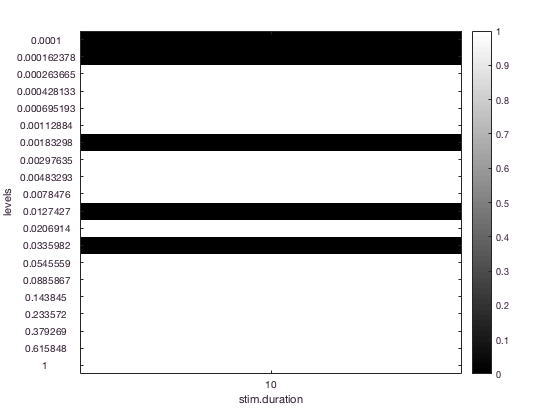

whichdec = mtrsp.decision.(conditions{2});
dec      = [];

for k1 = 1: nlevels
    for k2 = 1 : ndurations
        dec(k1, k2) = whichdec{k1, k2}.decVal;
    end
end

figure (2), clf, colormap gray
imagesc(1:length(durations),1:length(levels), dec), colorbar
set(gca, 'XTick', 1:length(durations), 'YTick', 1:length(levels), 'XTickLabels', durations, 'YTickLabels', levels);
ylabel('levels'), xlabel('stim.duration')